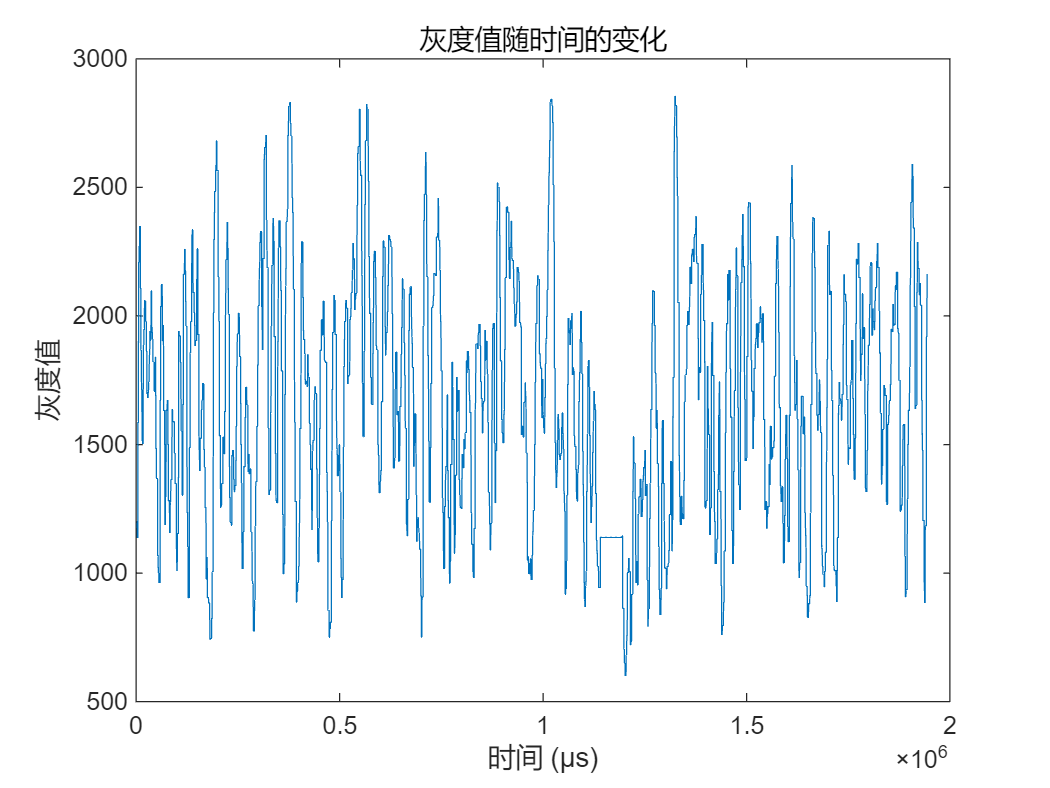

clear;

% 读取数据
rawdata = load('interpolatedData of Second round of data filtering.mat');
% rawdata = load('Second round of data filtering.mat');

% 绘制灰度随时间变化的图
plot(rawdata.interpolatedData(:,5), rawdata.interpolatedData(:,3));
% plot(rawdata.sorted_data(:,5), rawdata.sorted_data(:,3));
xlabel('时间 (μs)');
ylabel('灰度值');
title('灰度值随时间的变化');

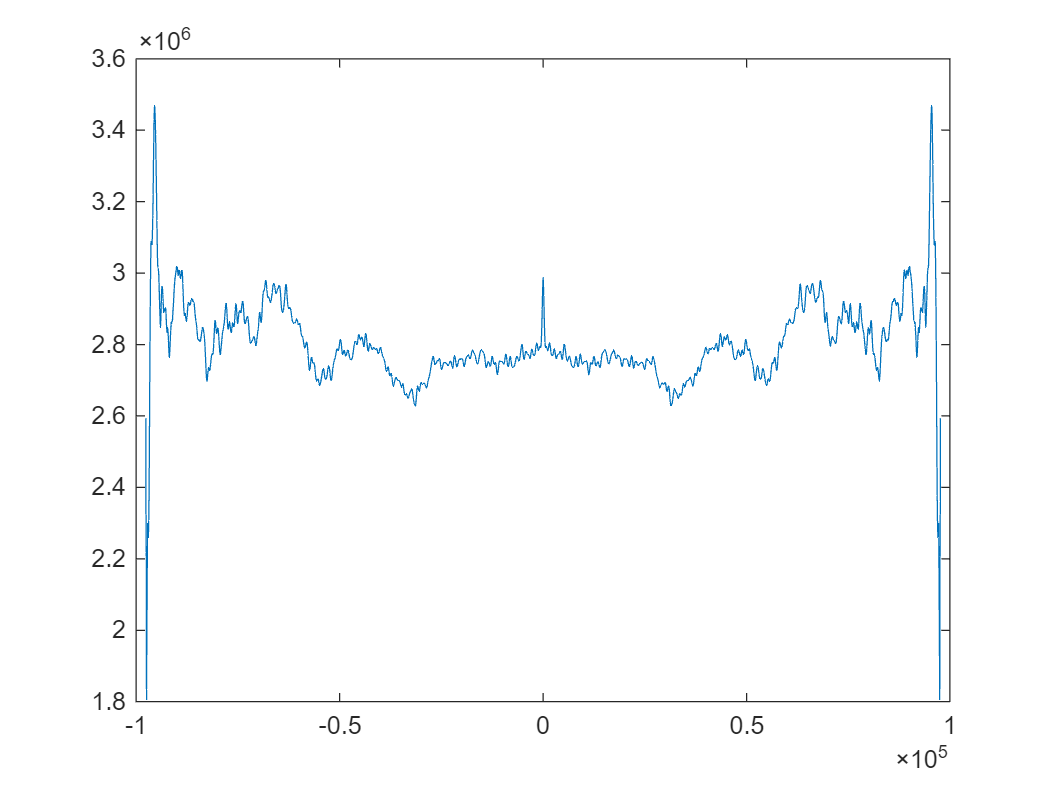


% 得到自相关图像
x = rawdata.interpolatedData(:,3);
% x = rawdata.sorted_data(:,3);
[a, b] = xcorr(x, 'unbiased');
% [a, b] = xcorr(x);
figure; % 创建新的图形窗口
plot(b, a);


% 找到 x 轴中点的索引
midpoint_index = round(length(b) / 2);

% 找到 x 轴中点的对应的 y 值
midpoint_y_value = a(midpoint_index);

% 找到以中点的 Y 值为起点的右侧的第一个极小值点
right_min_index = midpoint_index + 1; % 从中点的右侧开始搜索
while a(right_min_index) >= a(right_min_index + 1)
    right_min_index = right_min_index + 1;
end

% 返回该极小值点的X轴的值
right_min_x_value = b(right_min_index);

disp(['右侧的第一个极小值点的X轴的值：', num2str(right_min_x_value)]);

右侧的第一个极小值点的X轴的值：591



% 找到第一个极小值点的 Y 值
right_min_y_value = a(right_min_index);

% 找到这两个 Y 值的中间值
middle_y_value = (midpoint_y_value + right_min_y_value) / 2;

% 找到两个点对应的索引
start_index = min(midpoint_index, right_min_index);
end_index = max(midpoint_index, right_min_index);

% 在这两个索引之间找到最接近中间值的索引
[~, middle_index] = min(abs(a(start_index:end_index) - middle_y_value));

% 调整索引为全局索引
middle_index = middle_index + start_index - 1;

% 返回该点的 x 值
right_middle_x_value = b(middle_index);

disp(['最接近中间值的 X 轴的值：', num2str(right_middle_x_value)]);

最接近中间值的 X 轴的值：244



% 设定参数
n = 3.2; % 散斑尺寸（单位：像素）
k = 5.1667; % 像素实际尺寸（单位：μm/pixel）
delta_t = 20; % 事件相机输出间隔（单位：μs）

% 计算全高宽和半高宽
% full_height_width = 2 * right_min_x_value * delta_t * 10^-6; % 计算全高宽（单位：s）
half_height_width = 2 * right_middle_x_value * delta_t * 10^-6; % 计算半高宽（单位：s）

% 用全高宽计算速度
% t1 = full_height_width/2; % 一个散斑通过某固定像素所需的时间（单位：s）
% v1 = n * k * 10^-3 / t1; % 速度（单位：mm/s）

% 用半高宽计算速度
t2 = half_height_width; % 一个散斑通过某固定像素所需的时间（单位：s）
v2 = n * k * 10^-3 / t2; % 速度（单位：mm/s）

% disp(['全高宽：', num2str(full_height_width), 's']);
disp(['半高宽：', num2str(half_height_width), 's']);

半高宽：0.00976s


% disp(['一个散斑通过某固定像素所需的时间t1：', num2str(t1), 's']);
% disp(['速度v1：', num2str(v1), 'mm/s']);
disp(['一个散斑通过某固定像素所需的时间t2：', num2str(t2), 's']);

一个散斑通过某固定像素所需的时间t2：0.00976s


disp(['速度v2：', num2str(v2), 'mm/s']);

速度v2：1.694mm/s



% 打开文件以写入方式
fid = fopen('results.txt', 'w');

% 将内容写入文件
fprintf(fid, '散斑尺寸：%f 个像素\n', n);
fprintf(fid, '像素实际尺寸：%f μm/pixel\n', k);
fprintf(fid, '事件相机输出间隔：%f μs\n', delta_t);
fprintf(fid, '右侧的第一个极小值点的X轴的值：%f\n', right_min_x_value);
fprintf(fid, '最接近中间值的 X 轴的值：%f\n', right_middle_x_value);
% fprintf(fid, '全高宽：%f s\n', full_height_width);
fprintf(fid, '半高宽：%f s\n', half_height_width);
% fprintf(fid, '一个散斑通过某固定像素所需的时间t1：%f s\n', t1);
% fprintf(fid, '速度v1：%f mm/s\n', v1);
fprintf(fid, '一个散斑通过某固定像素所需的时间t2：%f s\n', t2);
fprintf(fid, '速度v2：%f mm/s\n', v2);

% 关闭文件
fclose(fid);

disp('结果已保存到 results.txt 文件中');

结果已保存到 results.txt 文件中
